# Representative Trajectory Tracking: 

This live script covers the testing of the current controller implementation in a trajectory deemed representative of what is expected of the UAV. It will also assess the effect of propeller efficiency losses on the capabilities of the platform, mainly as a benchmark for the latter adaptive control implementation. 

addpath("Models and Auxiliary Functions\")

## Model Definition: 

Begin by defining all model parameters and the controller. On the other hand, the $\Lambda$ matrix will be initialized on a case by case basis. 

%Specify gravitational acceleration: 
g=9.81; %[m/s^2]

%Geometric and Inertial Properties:
UAV.Nr = 6; %number of rotors
UAV.m = 1.2; %[kg] UAV mass
UAV.J = diag([0.01 0.01 0.018]); % [kg m^2] inertia matrix
UAV.r_bg = [0 0 0]'; %[m] center of mass location in the body frame -> note I change it to a column vector. 
UAV.S = UAV.m*cross_matrix(UAV.r_bg); % [kg m] static moment
UAV.MM=[UAV.m*eye(3,3),UAV.S';UAV.S,UAV.J];
UAV.MM_inv=inv(UAV.MM);

% Linear Aerodynamics
UAV.D_tauomega = diag([0.48 0.48 2.37]); %  angular velocity damping 
UAV.D_fv =  diag([0.055 0.055 0.022]); % linear velocity damping
UAV.D = [UAV.D_fv zeros(3,3); zeros(3,3) UAV.D_tauomega]; %-> there is a typo in the position of D_fv and D_tauomega on the data provided by the professor

% Propellers 
UAV.b = 0.215; %[m] arm length (ell in the slides)

k_f = 3.65e-6;                % [N/rad^2/s^2] Thrust characteristic coeff
sigma = 0.09;                 % [m] Torque-to-thrust ratio

%Construct input map:
%Rotors 1,3,5 rotate in the positive direction, 2,4,6 rotate in the
%negative direction
xiv=zeros(UAV.Nr,1);
xiv(1:2:UAV.Nr)=1; 
xiv(2:2:UAV.Nr)=-1;

gamma_r=2*pi/UAV.Nr*(0:UAV.Nr-1);
nr=[0;0;1];

F=nan(6,UAV.Nr);
for i=1:UAV.Nr
    pr=UAV.b*[cos(gamma_r(i));sin(gamma_r(i));0];
    pr_x=cross_matrix(pr);
    F(1:3,i)=nr;
    F(4:6,i)=(pr_x-xiv(i)*sigma*eye(3,3))*nr;
end

UAV.F=F;

%Actuator Dynamics: 
UAV.Omega_max = 10300; %[rpm] max spinning rate
UAV.Omega_min = 1260; %[rpm] min spinning rate
UAV.k_m = 1/0.05; % [s-1] Inverse of the time constant of the propeller motors

T_max=k_f*(UAV.Omega_max*2*pi/60)^2; %Unit conversion needed since kf is in N/(rad^2/s^2) and Omega_max and _min are given in rpm.
T_min=k_f*(UAV.Omega_min*2*pi/60)^2;

%For control allocation: (validated expression for F2 Plus)
F_2=F(3:6,:);
UAV.F_2_Plus=F_2'/(F_2*F_2');

%Define position controller: 
%Performance Goals: 
omega_n_p=1.75; %[rad/s]
zeta_p=0.8;    %[-]

%Convert to tuning: 
kp=omega_n_p^2;
kv=2*zeta_p*omega_n_p;

K_p=kp*eye(3,3);
K_v=kv*eye(3,3);

%Define attitude controller: 
%Tune controller: 
omega_n_a=20; %[rad/s]
zeta_a=1;     %[-]

%Tune k_r
k_r_hat=omega_n_a^2*diag(UAV.J);
A=[0,1,1;1,0,1;1,1,0];
k_r=A\k_r_hat;

%Tune K_omega:
K_omega=2*zeta_a*omega_n_a*UAV.J;

Then, initialize the trajectory at trim conditions on the appropriate point: 

%Initialize system: consider it starting from a trim condition at [0;0;0]
%Initialize postion and kinematics: 
p_b_i_0=[0;0;1];
q_0=[1;0;0;0];
v_b_0=[0;0;0];
omega_b_0=[0;0;0];
nu_b_0=[v_b_0;omega_b_0];

%Initialize rotor angular velocities: 
T_0=UAV.m*g/UAV.Nr; 
Omega_r_0=sqrt(T_0/k_f)*ones(UAV.Nr,1);

## Nominal Trajectory Tracking: 

We begin by assessing trajectory tracking in nominal conditions. To quantitatively assess the tracking capability, I will use a variant of the $L_2$ norm, applied pointwise on sample points in the trajectory. Detailed expressions can be found on the presentation. Let's begin by simply simulating the system and then plotting the trajectory against the reference. 

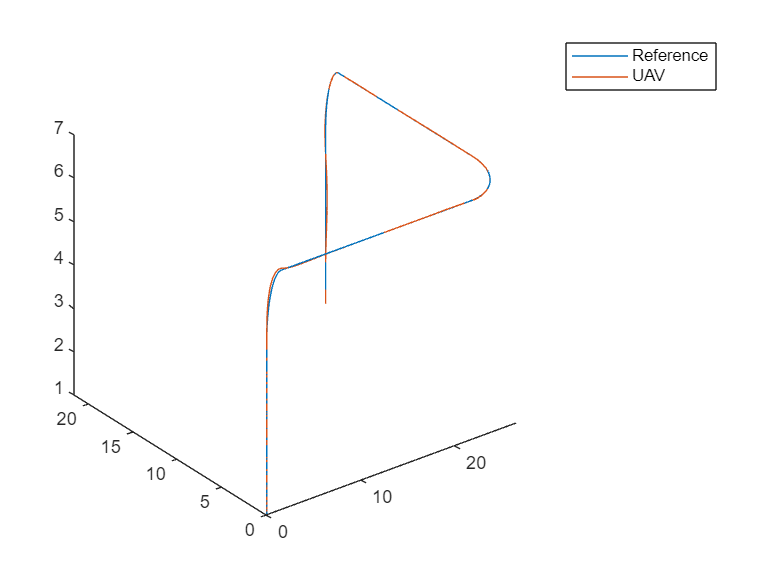

%Simulate system response: 
Lambda=eye(6,6);
R_turn_H=5;
R_turn_V=1.5;
simout=sim("UC_Trajectory_Model.slx","StopTime","25","RelTol","1e-6");
%Plot system response against reference trajectory: 
%System trajectory:
model_trajectory=nan(3,length(simout.p_b_i.time));

for i=1:length(simout.p_b_i.time)
    model_trajectory(:,i)=simout.p_b_i.data(:,1,i);
end

%Plot trajectory:
tv=linspace(0,25,1000);
ref_trajectory=nan(3,length(tv));

for i=1:length(tv)
    [ref_trajectory(:,i),~,~,~]=representative_trajectory(tv(i),R_turn_V,R_turn_H);
end

figure
clf
plot3(ref_trajectory(1,:),ref_trajectory(2,:),ref_trajectory(3,:),'DisplayName','Reference')
hold on
plot3(model_trajectory(1,:),model_trajectory(2,:),model_trajectory(3,:),'DisplayName','UAV')
legend()

It seems that the system will properly track this trajectory. I'll use it as a baseline for quantitatively assessing the effect of propeller efficiency loss. 

### Quantitative assessment with L2 (approx) norm: 

I'll use the trapezoid rule for integration: 

T=25; %simulation duration. 

%Evaluate reference trajectory at adequate timesteps:
model_velocity=nan(3,length(simout.v_i.time));
ref_position=nan(3,length(simout.p_b_i.time));
ref_velocity=nan(3,length(simout.v_i.time));

pos_integrand=nan(1,length(simout.p_b_i.time));
vel_integrand=nan(1,length(simout.v_i.time));

for i=1:length(simout.p_b_i.time)
    [ref_position(:,i),~,~,~]=representative_trajectory(simout.p_b_i.time(i),R_turn_V,R_turn_H);
    pos_integrand(i)=(model_trajectory(:,i)-ref_position(:,i))'*(model_trajectory(:,i)-ref_position(:,i));
end

for i=1:length(simout.v_i.time)
    [~,ref_velocity(:,i),~,~]=representative_trajectory(simout.v_i.time(i),R_turn_V,R_turn_H);
    model_velocity(:,i)=simout.v_i.data(:,1,i);
    vel_integrand(i)=(model_velocity(:,i)-ref_velocity(:,i))'*(model_velocity(:,i)-ref_velocity(:,i));
end


pos_Error=sqrt(1/T*(trapz(simout.p_b_i.time',pos_integrand)));
vel_Error=sqrt(1/T*(trapz(simout.p_b_i.time',vel_integrand)));

display(pos_Error)

pos_Error = 0.0572

display(vel_Error)

vel_Error = 0.1241

## Abnormal Trajectory Tracking: 90% efficiency everywhere

Qualitative assessment:

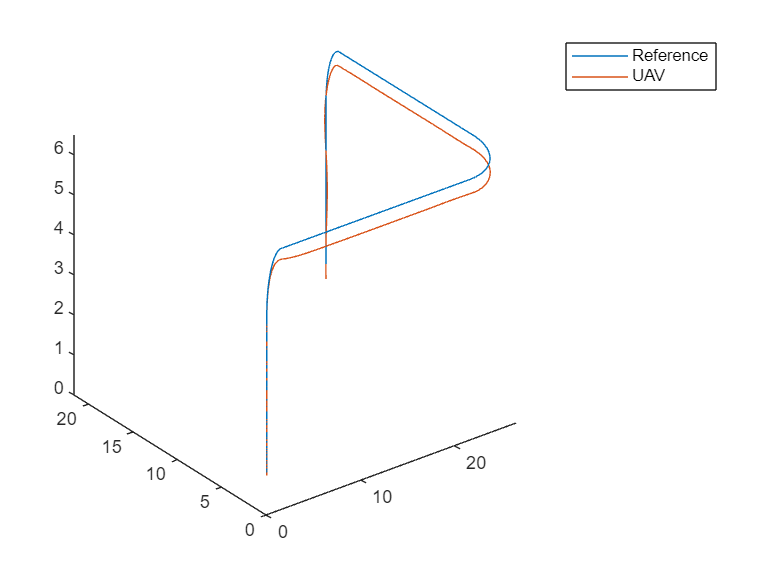

%Simulate system response: 
Lambda=0.9*eye(6,6);
R_turn_H=5;
R_turn_V=1.5;
simout=sim("UC_Trajectory_Model.slx","StopTime","25","RelTol","1e-6");
%Plot system response against reference trajectory: 
%System trajectory:
model_trajectory=nan(3,length(simout.p_b_i.time));

for i=1:length(simout.p_b_i.time)
    model_trajectory(:,i)=simout.p_b_i.data(:,1,i);
end

%Plot trajectory:
tv=linspace(0,25,1000);
ref_trajectory=nan(3,length(tv));

for i=1:length(tv)
    [ref_trajectory(:,i),~,~,~]=representative_trajectory(tv(i),R_turn_V,R_turn_H);
end

figure
clf
plot3(ref_trajectory(1,:),ref_trajectory(2,:),ref_trajectory(3,:),'DisplayName','Reference')
hold on
plot3(model_trajectory(1,:),model_trajectory(2,:),model_trajectory(3,:),'DisplayName','UAV')
legend()

Quantitative assessment: 

T=25; %simulation duration. 

%Evaluate reference trajectory at adequate timesteps:
model_velocity=nan(3,length(simout.v_i.time));
ref_position=nan(3,length(simout.p_b_i.time));
ref_velocity=nan(3,length(simout.v_i.time));

pos_integrand=nan(1,length(simout.p_b_i.time));
vel_integrand=nan(1,length(simout.v_i.time));

for i=1:length(simout.p_b_i.time)
    [ref_position(:,i),~,~,~]=representative_trajectory(simout.p_b_i.time(i),R_turn_V,R_turn_H);
    pos_integrand(i)=(model_trajectory(:,i)-ref_position(:,i))'*(model_trajectory(:,i)-ref_position(:,i));
end

for i=1:length(simout.v_i.time)
    [~,ref_velocity(:,i),~,~]=representative_trajectory(simout.v_i.time(i),R_turn_V,R_turn_H);
    model_velocity(:,i)=simout.v_i.data(:,1,i);
    vel_integrand(i)=(model_velocity(:,i)-ref_velocity(:,i))'*(model_velocity(:,i)-ref_velocity(:,i));
end


pos_Error=sqrt(1/T*(trapz(simout.p_b_i.time',pos_integrand)));
vel_Error=sqrt(1/T*(trapz(simout.p_b_i.time',vel_integrand)));

display(pos_Error)

pos_Error = 0.3529

display(vel_Error)

vel_Error = 0.1500

## Abnormal Trajectory Tracking: 80% efficiency everywhere

Qualitative assessment:

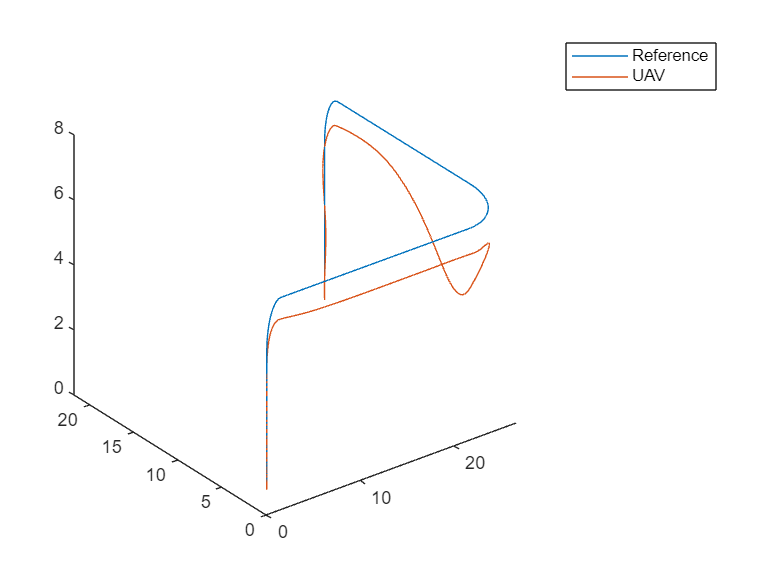

%Simulate system response: 
Lambda=0.8*eye(6,6);
R_turn_H=5;
R_turn_V=1.5;
simout=sim("UC_Trajectory_Model.slx","StopTime","25","RelTol","1e-6");
%Plot system response against reference trajectory: 
%System trajectory:
model_trajectory=nan(3,length(simout.p_b_i.time));

for i=1:length(simout.p_b_i.time)
    model_trajectory(:,i)=simout.p_b_i.data(:,1,i);
end

%Plot trajectory:
tv=linspace(0,25,1000);
ref_trajectory=nan(3,length(tv));

for i=1:length(tv)
    [ref_trajectory(:,i),~,~,~]=representative_trajectory(tv(i),R_turn_V,R_turn_H);
end

figure
clf
plot3(ref_trajectory(1,:),ref_trajectory(2,:),ref_trajectory(3,:),'DisplayName','Reference')
hold on
plot3(model_trajectory(1,:),model_trajectory(2,:),model_trajectory(3,:),'DisplayName','UAV')
legend()

Quantitative assessment: 

T=25; %simulation duration. 

%Evaluate reference trajectory at adequate timesteps:
model_velocity=nan(3,length(simout.v_i.time));
ref_position=nan(3,length(simout.p_b_i.time));
ref_velocity=nan(3,length(simout.v_i.time));

pos_integrand=nan(1,length(simout.p_b_i.time));
vel_integrand=nan(1,length(simout.v_i.time));

for i=1:length(simout.p_b_i.time)
    [ref_position(:,i),~,~,~]=representative_trajectory(simout.p_b_i.time(i),R_turn_V,R_turn_H);
    pos_integrand(i)=(model_trajectory(:,i)-ref_position(:,i))'*(model_trajectory(:,i)-ref_position(:,i));
end

for i=1:length(simout.v_i.time)
    [~,ref_velocity(:,i),~,~]=representative_trajectory(simout.v_i.time(i),R_turn_V,R_turn_H);
    model_velocity(:,i)=simout.v_i.data(:,1,i);
    vel_integrand(i)=(model_velocity(:,i)-ref_velocity(:,i))'*(model_velocity(:,i)-ref_velocity(:,i));
end


pos_Error=sqrt(1/T*(trapz(simout.p_b_i.time',pos_integrand)));
vel_Error=sqrt(1/T*(trapz(simout.p_b_i.time',vel_integrand)));

display(pos_Error)

pos_Error = 1.2853

display(vel_Error)

vel_Error = 0.5850

## Abnormal Trajectory Tracking: 85% efficiency everywhere

Qualitative assessment:

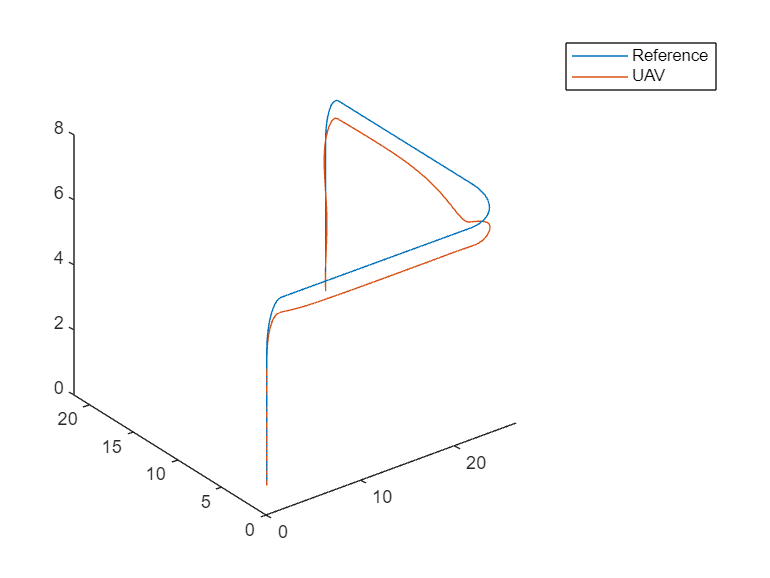

%Simulate system response: 
Lambda=0.85*eye(6,6);
R_turn_H=5;
R_turn_V=1.5;
simout=sim("UC_Trajectory_Model.slx","StopTime","25","RelTol","1e-6");
%Plot system response against reference trajectory: 
%System trajectory:
model_trajectory=nan(3,length(simout.p_b_i.time));

for i=1:length(simout.p_b_i.time)
    model_trajectory(:,i)=simout.p_b_i.data(:,1,i);
end

%Plot trajectory:
tv=linspace(0,25,1000);
ref_trajectory=nan(3,length(tv));

for i=1:length(tv)
    [ref_trajectory(:,i),~,~,~]=representative_trajectory(tv(i),R_turn_V,R_turn_H);
end

figure
clf
plot3(ref_trajectory(1,:),ref_trajectory(2,:),ref_trajectory(3,:),'DisplayName','Reference')
hold on
plot3(model_trajectory(1,:),model_trajectory(2,:),model_trajectory(3,:),'DisplayName','UAV')
legend()

Quantitative assessment: 

T=25; %simulation duration. 

%Evaluate reference trajectory at adequate timesteps:
model_velocity=nan(3,length(simout.v_i.time));
ref_position=nan(3,length(simout.p_b_i.time));
ref_velocity=nan(3,length(simout.v_i.time));

pos_integrand=nan(1,length(simout.p_b_i.time));
vel_integrand=nan(1,length(simout.v_i.time));

for i=1:length(simout.p_b_i.time)
    [ref_position(:,i),~,~,~]=representative_trajectory(simout.p_b_i.time(i),R_turn_V,R_turn_H);
    pos_integrand(i)=(model_trajectory(:,i)-ref_position(:,i))'*(model_trajectory(:,i)-ref_position(:,i));
end

for i=1:length(simout.v_i.time)
    [~,ref_velocity(:,i),~,~]=representative_trajectory(simout.v_i.time(i),R_turn_V,R_turn_H);
    model_velocity(:,i)=simout.v_i.data(:,1,i);
    vel_integrand(i)=(model_velocity(:,i)-ref_velocity(:,i))'*(model_velocity(:,i)-ref_velocity(:,i));
end


pos_Error=sqrt(1/T*(trapz(simout.p_b_i.time',pos_integrand)));
vel_Error=sqrt(1/T*(trapz(simout.p_b_i.time',vel_integrand)));

display(pos_Error)

pos_Error = 0.6349

display(vel_Error)

vel_Error = 0.2316

## Abnormal Trajectory Tracking: 95% efficiency everywhere

Qualitative assessment:

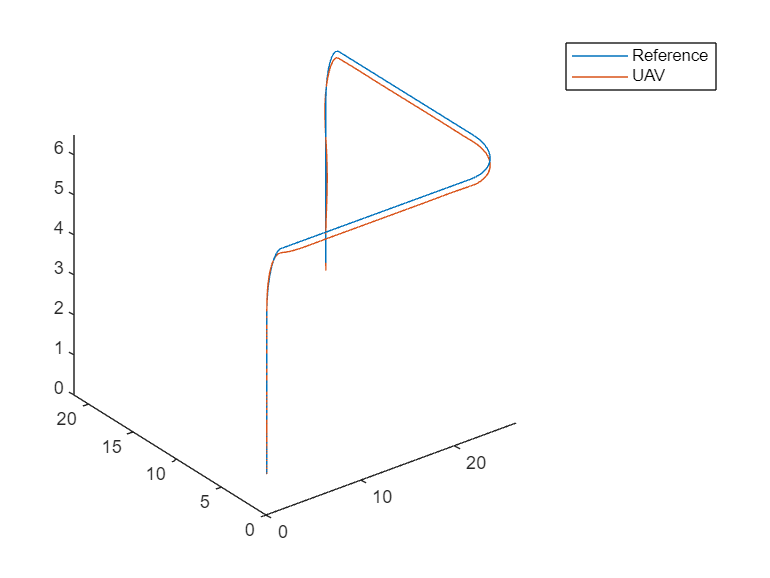

%Simulate system response: 
Lambda=0.95*eye(6,6);
R_turn_H=5;
R_turn_V=1.5;
simout=sim("UC_Trajectory_Model.slx","StopTime","25","RelTol","1e-6");
%Plot system response against reference trajectory: 
%System trajectory:
model_trajectory=nan(3,length(simout.p_b_i.time));

for i=1:length(simout.p_b_i.time)
    model_trajectory(:,i)=simout.p_b_i.data(:,1,i);
end

%Plot trajectory:
tv=linspace(0,25,1000);
ref_trajectory=nan(3,length(tv));

for i=1:length(tv)
    [ref_trajectory(:,i),~,~,~]=representative_trajectory(tv(i),R_turn_V,R_turn_H);
end

figure
clf
plot3(ref_trajectory(1,:),ref_trajectory(2,:),ref_trajectory(3,:),'DisplayName','Reference')
hold on
plot3(model_trajectory(1,:),model_trajectory(2,:),model_trajectory(3,:),'DisplayName','UAV')
legend()

Quantitative assessment: 

T=25; %simulation duration. 

%Evaluate reference trajectory at adequate timesteps:
model_velocity=nan(3,length(simout.v_i.time));
ref_position=nan(3,length(simout.p_b_i.time));
ref_velocity=nan(3,length(simout.v_i.time));

pos_integrand=nan(1,length(simout.p_b_i.time));
vel_integrand=nan(1,length(simout.v_i.time));

for i=1:length(simout.p_b_i.time)
    [ref_position(:,i),~,~,~]=representative_trajectory(simout.p_b_i.time(i),R_turn_V,R_turn_H);
    pos_integrand(i)=(model_trajectory(:,i)-ref_position(:,i))'*(model_trajectory(:,i)-ref_position(:,i));
end

for i=1:length(simout.v_i.time)
    [~,ref_velocity(:,i),~,~]=representative_trajectory(simout.v_i.time(i),R_turn_V,R_turn_H);
    model_velocity(:,i)=simout.v_i.data(:,1,i);
    vel_integrand(i)=(model_velocity(:,i)-ref_velocity(:,i))'*(model_velocity(:,i)-ref_velocity(:,i));
end


pos_Error=sqrt(1/T*(trapz(simout.p_b_i.time',pos_integrand)));
vel_Error=sqrt(1/T*(trapz(simout.p_b_i.time',vel_integrand)));

display(pos_Error)

pos_Error = 0.1741

display(vel_Error)

vel_Error = 0.1328

## Abnormal Trajectory Tracking: 75% efficiency everywhere

Qualitative assessment:

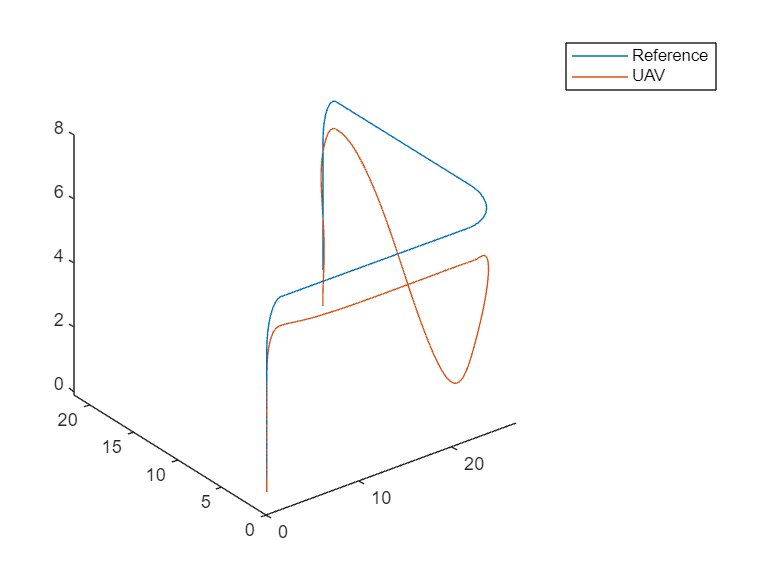

%Simulate system response: 
Lambda=0.75*eye(6,6);
R_turn_H=5;
R_turn_V=1.5;
simout=sim("UC_Trajectory_Model.slx","StopTime","25","RelTol","1e-6");
%Plot system response against reference trajectory: 
%System trajectory:
model_trajectory=nan(3,length(simout.p_b_i.time));

for i=1:length(simout.p_b_i.time)
    model_trajectory(:,i)=simout.p_b_i.data(:,1,i);
end

%Plot trajectory:
tv=linspace(0,25,1000);
ref_trajectory=nan(3,length(tv));

for i=1:length(tv)
    [ref_trajectory(:,i),~,~,~]=representative_trajectory(tv(i),R_turn_V,R_turn_H);
end

figure
clf
plot3(ref_trajectory(1,:),ref_trajectory(2,:),ref_trajectory(3,:),'DisplayName','Reference')
hold on
plot3(model_trajectory(1,:),model_trajectory(2,:),model_trajectory(3,:),'DisplayName','UAV')
legend()

Quantitative assessment: 

T=25; %simulation duration. 

%Evaluate reference trajectory at adequate timesteps:
model_velocity=nan(3,length(simout.v_i.time));
ref_position=nan(3,length(simout.p_b_i.time));
ref_velocity=nan(3,length(simout.v_i.time));

pos_integrand=nan(1,length(simout.p_b_i.time));
vel_integrand=nan(1,length(simout.v_i.time));

for i=1:length(simout.p_b_i.time)
    [ref_position(:,i),~,~,~]=representative_trajectory(simout.p_b_i.time(i),R_turn_V,R_turn_H);
    pos_integrand(i)=(model_trajectory(:,i)-ref_position(:,i))'*(model_trajectory(:,i)-ref_position(:,i));
end

for i=1:length(simout.v_i.time)
    [~,ref_velocity(:,i),~,~]=representative_trajectory(simout.v_i.time(i),R_turn_V,R_turn_H);
    model_velocity(:,i)=simout.v_i.data(:,1,i);
    vel_integrand(i)=(model_velocity(:,i)-ref_velocity(:,i))'*(model_velocity(:,i)-ref_velocity(:,i));
end


pos_Error=sqrt(1/T*(trapz(simout.p_b_i.time',pos_integrand)));
vel_Error=sqrt(1/T*(trapz(simout.p_b_i.time',vel_integrand)));

display(pos_Error)

pos_Error = 2.3320

display(vel_Error)

vel_Error = 1.0102

## Conclusions: 

I have identified an interesting trajectory for the system. That is, a trajectory representative of its capabilities and in which the degradation of performance has a noticeable effect. This trajectory will become the baseline case for the development of later tasks.